%{
Name: Water Tank Fill-and-Drain 
Author: Evan Scheuritzel
Version: 1.0
Purpose: inspect how a water tank fills up over time.
Input: none
Output: Graph containg volume Data and important points
%}

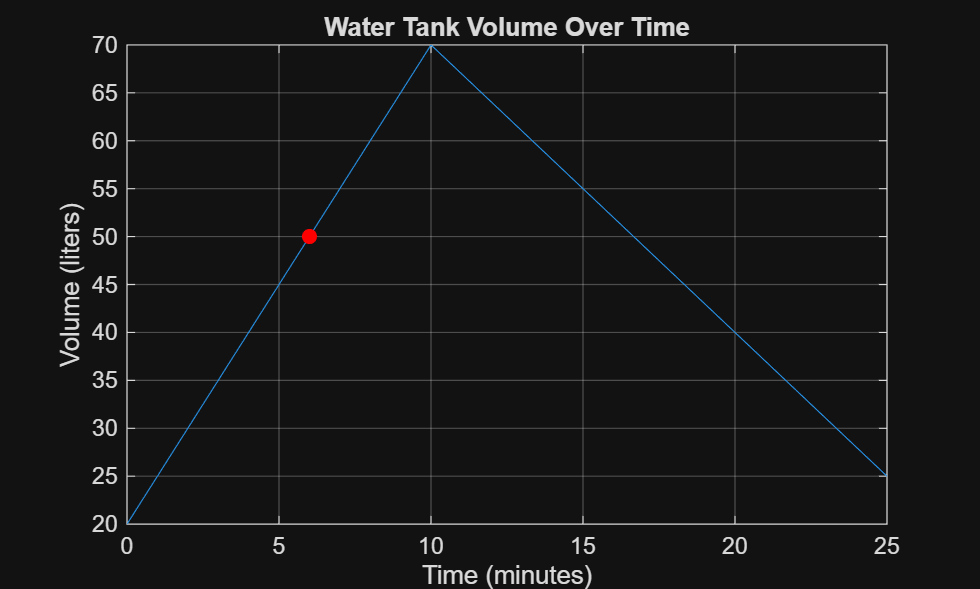

Volume reaches 50 L at t = 6 minutes.


clear
Vol =[];
for t = 0:25

    if t < 10
        V = 5*t+20;
    else
        V = -3*(t-10)+70;
    end
    Vol = [Vol, V];
end
i = 0:25;
plot(i,Vol)
xlabel('Time (minutes)');
ylabel('Volume (liters)');
title('Water Tank Volume Over Time');
grid on;
% find first time index where volume is >= 50 liters
idx = find(Vol >= 50, 1, 'first');
if isempty(idx)
    fprintf('Volume never reaches 50 L in the simulated period.\n');
else
    t_reach = i(idx);
    fprintf('Volume reaches 50 L at t = %d minutes.\n', t_reach);
    hold on
    plot(t_reach, Vol(idx), 'ro', 'MarkerFaceColor','r')
    hold off
end